# Optimización por Colonia de Hormigas (ACO) para Caminos Hamiltonianos

**Profesor:** PhD. Marlon Moscoso Martínez

%Inicialización
clc; clear all; close all;
disp('===== ACO PARA CAMINOS HAMILTONIANOS =====');

===== ACO PARA CAMINOS HAMILTONIANOS =====


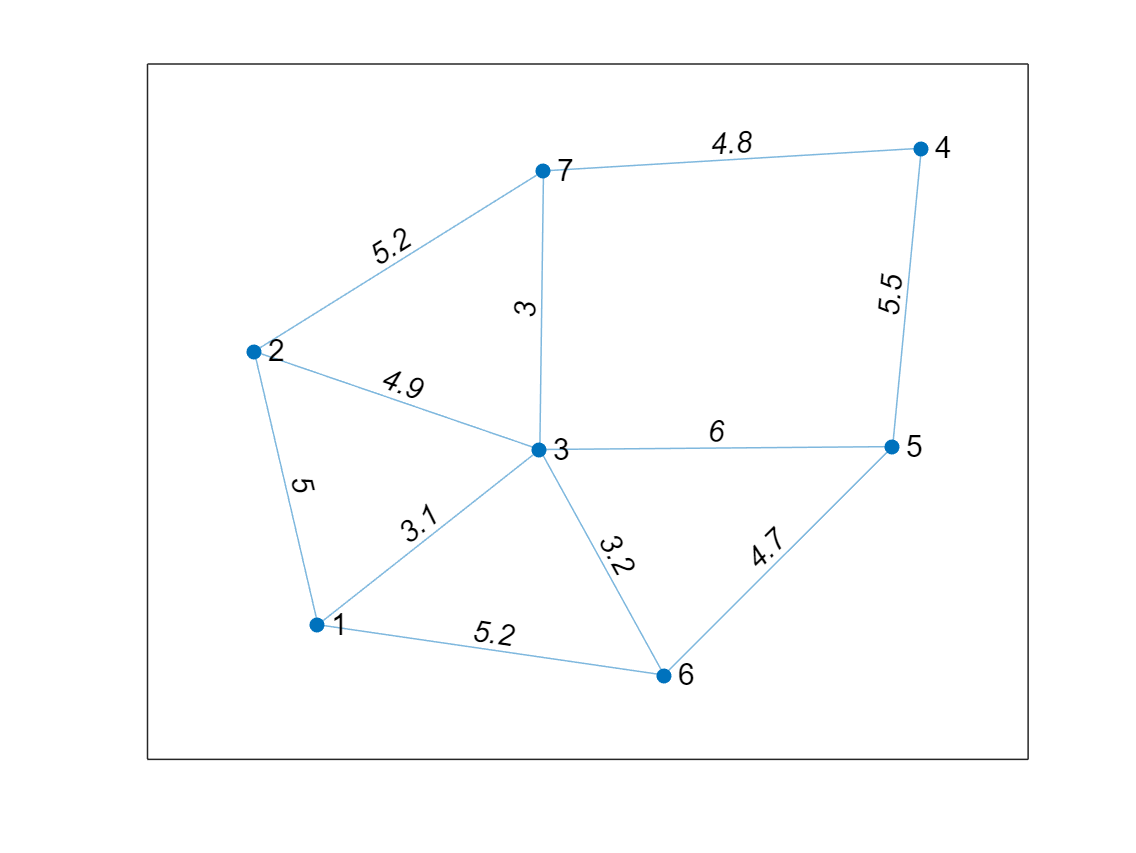


%Definicion de los nodos y pesos 
nodos1 = [1 1 1 2 2 6 6 3 3 5 7];
nodos2 = [2 3 6 7 3 3 5 7 5 4 4];
peso =   [5 3.1 5.2 5.2 4.9 3.2 4.7 3 6 5.5 4.8];
G = graph(nodos1,nodos2,peso);
plot(G,'EdgeLabel',G.Edges.Weight)


%Inicializacion de las variables a implementar
inicio = 1;
respaldo = inicio;
inicio1 = inicio;
inicio2 = inicio;
inicio3 = inicio;
inicio4 = inicio;
fin = 4;
n=0;
visibilidad = 1./peso;

%Feromonas
taoxn = ones(1,length(nodos1))/(length(nodos1) - 1);
taoxn1 = taoxn;
taoxn2 = taoxn;
taoxn3 = taoxn;
taoxn4 = taoxn;
feromonas = taoxn.*(1-0.1);

%Caminos
camino = [inicio];
camino1 = camino;
camino2 = camino;
camino3 = camino;
camino4 = camino;

%Costos
costo_total = [0];
costo_total1 = costo_total;
costo_total2 = costo_total;
costo_total3 = costo_total;
costo_total4 = costo_total;

%Posiciones 
posiciones =  [0];
posiciones1 = [0];
posiciones2 = [0];
posiciones3 = [0];
posiciones4 = [0];

%Probabilidades
Pxy = [];
Pxy_acum = [];
Pxy1 = [];
Pxy_acum1 = [];
Pxy2 = [];
Pxy_acum2 = [];
Pxy3 = [];
Pxy_acum3 = [];
Pxy4 = [];
Pxy_acum4 = [];

%Numero de iteraciones a implementar
r = 50;

%% Generacion de hormigas
for k=1:r
    while(inicio ~= fin)
    %hormiga 1
    indices = find( nodos1 == inicio);
    [taoxn,taoxn_acum,Pxy,Pxy_acum] = Probabilidades(indices,taoxn,visibilidad);
    aleatorio = rand;
    [camino,inicio,costo_total,posiciones] = Camino(aleatorio,Pxy_acum,nodos2,indices,camino,inicio,peso,costo_total,posiciones);
    end
    while(inicio1 ~= fin)
    %hormiga 2
    indices1 = find( nodos1 == inicio1);
    [taoxn1,taoxn_acum1,Pxy1,Pxy_acum1] = Probabilidades(indices1,taoxn1,visibilidad);
    aleatorio1 = rand;
    [camino1,inicio1,costo_total1,posiciones1] = Camino(aleatorio1,Pxy_acum1,nodos2,indices1,camino1,inicio1,peso,costo_total1,posiciones1);
    end
    while(inicio2 ~= fin)
    %hormiga 3
    indices2 = find( nodos1 == inicio2 );
    [taoxn2,taoxn_acum2,Pxy2,Pxy_acum2] = Probabilidades(indices2,taoxn2,visibilidad);
    aleatorio2 = rand;
    [camino2,inicio2,costo_total2,posiciones2] = Camino(aleatorio2,Pxy_acum2,nodos2,indices2,camino2,inicio2,peso,costo_total2,posiciones2);
    end 
    while(inicio3 ~= fin)
    %hormiga 4
    indices3 = find( nodos1 == inicio3 );
    [taoxn3,taoxn_acum3,Pxy3,Pxy_acum3] = Probabilidades(indices3,taoxn3,visibilidad);
    aleatorio3 = rand;
    [camino3,inicio3,costo_total3,posiciones3] = Camino(aleatorio3,Pxy_acum3,nodos2,indices3,camino3,inicio3,peso,costo_total3,posiciones3);
    end  
    while(inicio4 ~= fin)
    %hormiga 5
    indices4 = find( nodos1 == inicio4 );
    [taoxn4,taoxn_acum4,Pxy4,Pxy_acum4] = Probabilidades(indices4,taoxn4,visibilidad);
    aleatorio4 = rand;
    [camino4,inicio4,costo_total4,posiciones4] = Camino(aleatorio4,Pxy_acum4,nodos2,indices4,camino4,inicio4,peso,costo_total4,posiciones4);
    end

    %obtencion de los costos totales
    costo_total = sum(costo_total);
    costo_total1 = sum(costo_total1);
    costo_total2 = sum(costo_total2);
    costo_total3 = sum(costo_total3);
    costo_total4 = sum(costo_total4);
    
    %vector ferononas el cual se va actualizando cada bucle
    for i=2:length(posiciones)
       feromonas(posiciones(i)) =  feromonas(posiciones(i)) + 1/costo_total;
    end
    for i=2:length(posiciones1)
       feromonas(posiciones1(i)) =  feromonas(posiciones1(i)) + 1/costo_total1;
    end
    for i=2:length(posiciones2)
       feromonas(posiciones2(i)) =  feromonas(posiciones2(i)) + 1/costo_total2;
    end
    for i=2:length(posiciones3)
       feromonas(posiciones3(i)) =  feromonas(posiciones3(i)) + 1/costo_total3;
    end
    for i=2:length(posiciones4)
       feromonas(posiciones4(i)) =  feromonas(posiciones4(i)) + 1/costo_total4;
    end
    
    % Se carga el valor del vector previamente actaulizado de feromonas
    % para la sigueinte iteracion
    taoxn1 = feromonas;
    taoxn  = feromonas;
    taoxn2 = feromonas;
    taoxn3 = feromonas;
    taoxn4 = feromonas;
    
    % Se limpian los valores para la nueva iteracion
    if k<r
        inicio = respaldo;
        inicio1 = inicio;
        inicio2 = inicio;
        inicio3 = inicio;
        inicio4 = inicio;
        fin = 4;
        n=0;
        visibilidad = 1./peso;
        camino = [inicio];
        camino1 = camino;
        camino2 = camino;
        camino3 = camino;
        camino4 = camino;
        costo_total = [0];
        costo_total1 = costo_total;
        costo_total2 = costo_total;
        costo_total3 = costo_total;
        costo_total4 = costo_total;
        posiciones = [0];
        posiciones1 = [0];
        posiciones2 = [0];
        posiciones3 = [0];
        posiciones4 = [0];
        Pxy = [];
        Pxy_acum = [];
        Pxy1 = [];
        Pxy_acum1 = [];
        Pxy2 = [];
        Pxy_acum2 = [];
        Pxy3 = [];
        Pxy_acum3 = [];
        Pxy4 = [];
        Pxy_acum4 = [];
    end
    
end

% Impresion de resultados
disp(['Camino recorrido por hormiga1: [ ',num2str(camino),' ]']);

Camino recorrido por hormiga1: [ 1  2  3  7  4 ]


disp(['Camino recorrido por hormiga2: [ ',num2str(camino1),' ]']);

Camino recorrido por hormiga2: [ 1  3  7  4 ]


disp(['Camino recorrido por hormiga3: [ ',num2str(camino2),' ]']);

Camino recorrido por hormiga3: [ 1  3  7  4 ]


disp(['Camino recorrido por hormiga4: [ ',num2str(camino3),' ]']);

Camino recorrido por hormiga4: [ 1  3  7  4 ]


disp(['Camino recorrido por hormiga5: [ ',num2str(camino4),' ]']);

Camino recorrido por hormiga5: [ 1  3  7  4 ]


disp(['Costo total hormiga 1: ',num2str(costo_total)]);

Costo total hormiga 1: 17.7


disp(['Costo total hormiga 2: ',num2str(costo_total1)]);

Costo total hormiga 2: 10.9


disp(['Costo total hormiga 3: ',num2str(costo_total2)]);

Costo total hormiga 3: 10.9


disp(['Costo total hormiga 4: ',num2str(costo_total3)]);

Costo total hormiga 4: 10.9


disp(['Costo total hormiga 5: ',num2str(costo_total4)]);

Costo total hormiga 5: 10.9




function [taoxn,taoxn_acum,Pxy,Pxy_acum] = Probabilidades(indices,taoxn,visibilidad)
    taoxn_acum = 0;   
    
    % Funciones que permite el calculo la probabilidades individuales y
    % acumuladas las cuales son necesarias para la obtencion de los caminos
    for i=1:length(indices)
       taoxn(indices(i)) = taoxn(indices(i)) * visibilidad(indices(i));
       taoxn_acum = taoxn_acum + taoxn(indices(i));
    end
    for i=1:length(indices)
       Pxy(i) = taoxn(indices(i)) / taoxn_acum;
       if i == 1
            Pxy_acum(i) = Pxy(i) ;
       else
            Pxy_acum(i) = Pxy_acum(i-1) + Pxy(i);
       end
      
       
    end
end


function [camino,inicio,costo_total,posiciones] = Camino(aleatorio,Pxy_acum,nodos2,indices,camino,inicio,peso,costo_total,posiciones)
   
    %Funcion para obtener el camino, el nuevo inicio, y el costo total, esta
    %funcion se repetira hasta llegar al ultimo nodo.
       for i=1:length(Pxy_acum)
           %Bucle para comparar el valor aleatorio con las probabilidades
           %acumuladas
       if i == 1
          if (0<=aleatorio)&&(aleatorio<=Pxy_acum(i))
              x = i;
              break;    
          end
       end
       if i<length(Pxy_acum)
       valor_previo = Pxy_acum(i);
       valor_posterior = Pxy_acum(i+1);
       
       if (valor_previo <= aleatorio) && (aleatorio <= valor_posterior)
          x = i+1;
          break;
       end
       end
       
   end
   c = indices(x);
   posiciones = [posiciones,c];
   inicio = nodos2(c);
   camino = [camino,nodos2(c)];
   costo_total = [costo_total,peso(c)];
end